`Wczytanie bazy danych do MatLab'a do zmiennej data`

clearvars;
clc;
data = readtable('player_mvp_stats.csv','PreserveVariableNames',true);

#### `Baza danych posiada rekordy odnośnie notowanych graczy mvp w latach 1991-2021 z danymi m.in. wieku, spędzonego czasu na boisku, rzutów, skuteczności itp.`

# `Wstęp`

    `Celem projektu końcowego z przedmiotu było przeprowadzenie i odpowiedzenie na wybrane pytania badawcze w oparciu o dobrane bazy danych. Badanie przeprowadzone przez nasz zespół koncentrowało się na najlepszych zawodnikach ligi NBA w latach 1991 – 2021 wybranych w drodze plebiscytu nagród MVP. Dane do analizy pozyskano ze strony kaggle.com, funkcjonująca jako użyteczna baza wielu danych. Link do wykorzystanych rekordów znajduje się w bibliografii na końcu sprawozdania.  `

`Operowaliśmy na danych dotyczących: `

- `wieku zawodników,  `

- `statystyk skuteczności dotyczących wykonywania rzutów osobistych (linia 4 metrów),  `

- `zapisach średniego spędzonego czasu zawodników na boisku w trakcie meczu, `

- `zapisach rozegranych meczy na sezon (maksymalnie 82 mecze w sezonie), `

- `zestawień pozycji, gdzie: C - środkowy; PF – silny skrzydłowy; SF – niski skrzydłowy;  SG - rzucający obrońca; PG - rozgrywający. `

`       Wyznaczyliśmy również podstawowe cele naszej analizy: `

- `weryfikacja, czy wiek zawodników różnicuje średni czas pobytu na boisku, `

- `estymowanie skuteczności graczy MVP, `

- `sprawdzenie, zależności pozycji graczy od ich skuteczności, `

- `porównanie średnich meczy na sezon klubu Los Angeles Lakers względem pozostałych klubów. `

`Przeprowadzamy, więc analizę struktury (rozkładu zbiorowości względem wybranych cech) oraz współzależności (związków pomiędzy cechami), przy czym warto zauważyć, iż operujemy na danych jakościowych i ilościowych. Dążąc do odpowiedzi na założone pytania i przetestowania hipotez przeprowadzono analizę statystyczną za pomocą programu Matlab w wersji R2021b. Korzystając z dostępnych narzędzi przeprowadzono analizę ANOVA wraz z testem Kruskala-Wallisa, testem Shapiro-Wilka oraz analizą Post-Hoc, wykonano estymację parametrów na podstawie przedziałów ufności dla średniej o dużej próbie przy pomocy statystyki testującej i wybranego modelu numer III, zbadano korelację przy pomocy tablicy krzyżowej oraz skorzystano z testu Manna-Whitneya przy testach dla średnich. Przyjęto również za poziom istotności alfa = 0.01, przyjmujemy więc 1% ryzyko na niewystąpienie wykazanych efektów w rzeczywistości, jednak na potrzeby projektu i omawianych danych takie ryzyko jest rozsądne i akceptowalne. `

# `Anova`

`Czy 'wiek' różnicuje średni pobyt na boisku ?`

- `Przygotowanie danych do analizy:`

data_Sorted = sortrows(data,'Age');
data_Sorted_Age = table2array([data_Sorted(:,3) data_Sorted(:,7)]);
data_Sorted_Groups = [];
iterator = 1;
i = 1;
j = 1;
age_Control = 0;
for iterator = 1:size(data_Sorted,1)
    if data_Sorted_Age(iterator,1) == 18 + age_Control
        data_Sorted_Groups(i,j) = data_Sorted_Age(iterator,2);
        i = i + 1;
    elseif data_Sorted_Age(iterator,1) ~= 18 + age_Control
        age_Control = age_Control + 1;
        i = 1;
        j = j + 1;
        data_Sorted_Groups(i,j) = data_Sorted_Age(iterator,2);
    end
end
for iterator = 1:numel(data_Sorted_Groups)
    if data_Sorted_Groups(iterator) == 0
        data_Sorted_Groups(iterator) = NaN;
    end
end
data_Sorted_Groups_Table = array2table(data_Sorted_Groups);

`W celu zbadania wyżej postawionego pytania skorzystano z analizy ANOVA przy uprzednim zweryfikowaniu i dobraniu danych oraz sprawdzeniu założeń wykorzystywanej metody statystycznej. Zestawienie odpowiednio podzielono na grupy wiekowe od 18 do 44 lat w połączeniu ze statystyką średniego czasu spędzonego na boisku.`

`Sprawdzamy kolejne założenia:`

#### `Mierzalność analizowanych zmiennych:`

`Mierzalność jest spełniona. Wyrażone w wartościach liczbowych.`

#### `Niezależność zmiennych losowych w rozważanych populacjach:`

`Czy powtarzalność w kolejnych latach jest zależnością ?`

`Zakładam w takim razie, że zawodnicy, którzy otrzymali kilkukrotnie nagrodę nie są powtarzalnością biorąc pod uwagę zmienność formy, warunków oraz wieku zawodników.`

#### `Równoliczność analizowanych grup:`

`Grupy są nierównoliczne, czyli przechodzimy do Kruskala-Wallisa.`

#### `Normalność rozkładu zmiennych w każdej populacji:`

`H0: Dane (w każdej podgrupie) pochodzą z rozkładu normalnego.`

`H1: Dane (przynjamniej w jednej z podgrupie) nie pochodzą z rozkładu normalnego.`

% swtest daje 0 - nie odrzucać hipotezy zerowej

for iterator = 1:size(data_Sorted_Groups,2)-2
    is_Data_Normal(iterator) = swtest(data_Sorted_Groups(:,iterator),0.05);
end
is_Data_Normal

is_Data_Normal = 1×25 logical array
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0


`Pomimo nie spełnienia warunku równoliczności sprawdzam normalność i jednorodność, z zastrzeżeniem do 25 grup, ponieważ dwie ostatnie są pojedyńczymi przypadkami. Zakładam, więc, że są to przypadki nie wpływające na analizę i kontynuuję z 25 grupami podziału. Warto podkreślić iż, są to nieliczne przypadki w całym zbiorze danych.`

#### `Jednorodność wariancji:`

`Niewymagana sprawdzenia - przeprowadzona jedynie w celu otrzymania informacji o podgrupach analizy.`

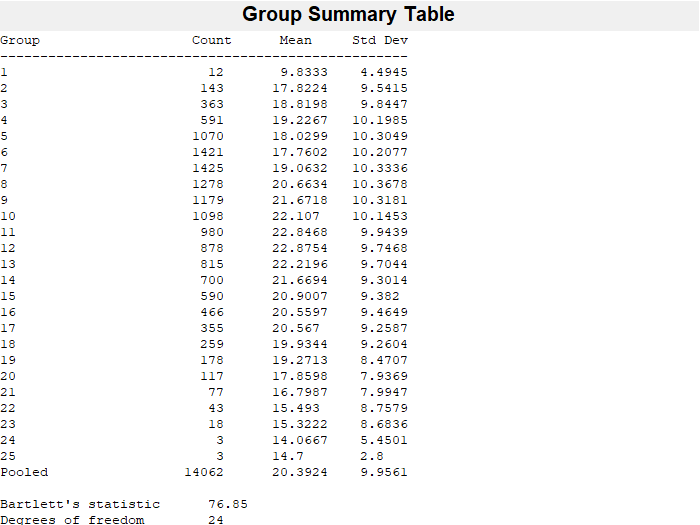

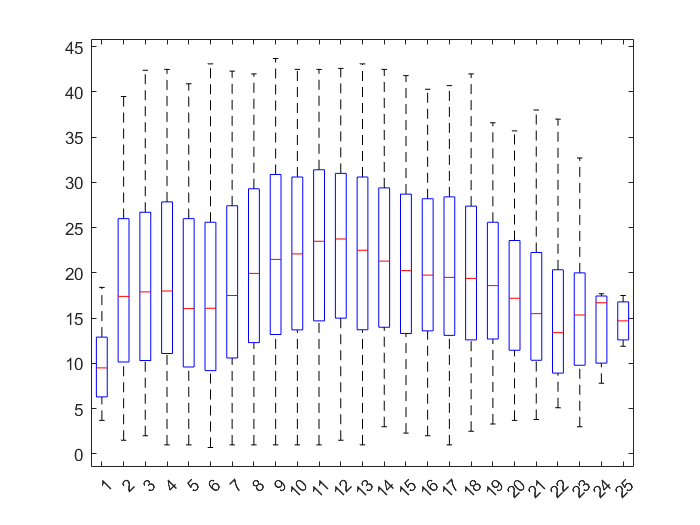

[p stats] = vartestn(data_Sorted_Groups(:,1:25));

#### `Analiza ANOVA:`

`Założenie równoliczności niespełnione przechodzimy do:`

`Test Kruskalla-Wallisa:`

`Ho: Dane w każdej kolumnie macierzy pochodzą z tego samego rozkładu,`

`H1: Nie wszystkie próbki pochodzą z tego samego rozkładu`

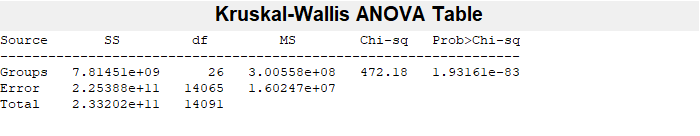

p = 1.9316e-83

tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df'   }    {'MS'        }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Groups'}    {[7.8145e+09]}    {[   26]}    {[3.0056e+08]}    {[472.1831]}    {[ 1.9316e-83]}
    {'Error' }    {[2.2539e+11]}    {[14065]}    {[1.6025e+07]}    {0×0 double}    {0×0 double   }
    {'Total' }    {[2.3320e+11]}    {[14091]}    {0×0 double  }    {0×0 double}    {0×0 double   }


stats = struct with fields:
       gnames: {27×1 cell}
            n: [12 144 364 592 1071 1422 1427 1280 1180 1100 981 879 816 701 591 467 356 260 179 118 78 44 19 4 4 2 1]
       source: 'kruskalwallis'
    meanranks: [2.6845e+03 6.0727e+03 6.4159e+03 6.5788e+03 6.0746e+03 5.9756e+03 6.4915e+03 7.1424e+03 7.5503e+03 7.7365e+03 8.0430e+03 8.0694e+03 7.7958e+03 7.5863e+03 7.2774e+03 7.1335e+03 7.1514e+03 6.8822e+03 6.6322e+03 6.0459e+03 5.6498e+03 … ]
         sumt: 23567076


array_Data = data_Sorted_Age(:,2)';
array_Labels = data_Sorted_Age(:,1)';
[p,tbl,stats] = kruskalwallis(array_Data,array_Labels)

`Odp: P-value 1.93e-83 jest mniejsze od alfa = 0.01, co sugeruje odrzucenie hipoztezy zerowej i przyjęcie hipotezy alternatywnej, iż nie wszystkie próbki pochodzą z tego samego rozkładu.`

`Implikacją takiego wyniku analizy jest wniosek – w odniesieniu do tematu naszych rozważań - iż wiek różnicuje średni czas spędzony na boisku przez zawodników MVP. W wyniku analizy otrzymujemy, więc wniosek, który możemy odnieść do dyspozycyjności oraz formy kolejnych zawodników MVP i jest ona zależna od wieku. `

#### `Analiza Post-hoc!`

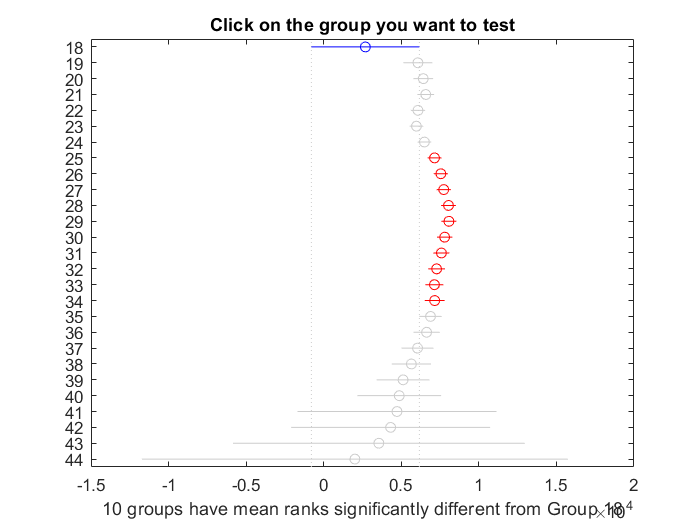

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


c = 	1.0e+04 *

    0.0001    0.0002   -0.7906   -0.3388    0.1130    0.0001
    0.0001    0.0003   -0.8143   -0.3731    0.0681    0.0000
    0.0001    0.0004   -0.8279   -0.3894    0.0490    0.0000
    0.0001    0.0005   -0.7755   -0.3390    0.0975    0.0000
    0.0001    0.0006   -0.7650   -0.3291    0.1068    0.0001
    0.0001    0.0007   -0.8166   -0.3807    0.0552    0.0000
    0.0001    0.0008   -0.8819   -0.4458   -0.0097    0.0000
    0.0001    0.0009   -0.9229   -0.4866   -0.0503    0.0000
    0.0001    0.0010   -0.9417   -0.5052   -0.0687    0.0000
    0.0001    0.0011   -0.9726   -0.5358   -0.0991    0.0000


c = multcompare(stats)

`W analizie Post-Hoc możemy zauważyć, iż większość grup wiekowych o dużej liczebności w zakresie od 19 do 30 lat znacznie różnią się od kilku pozostałych grup. Tendencję tą wykazuje większość grup, a zespoły o małej liczebności można traktować jako obserwacje odstające, gdyż rozrzut wartości powodowany jest jedynie kilkoma obserwacjami w porównaniu do dużych obserwacji. Jednak widząc trend w grupach licznych możemy wnioskować, iż rozszerzenie grup lub zawężenie zakresu analizy nie zmieniłoby efektów i wyników badania. Możemy również wysunąć hipotezy na temat określonych grup wiekowych i różnicowania wiekiem m.in. zawodnicy młodsi spędzają mniej czasu na boisku – powodem może być mniejsze doświadczenie i mniej pobłażliwe podejście trenerskie, również i najstarsi spędzają mniej czasu na boisku – tu jednak powodu można doszukiwać się w spadku formy czy wytrzymałości graczy i podejściu “oszczędnym” trenerów do zawodników. `

# `Porównanie średnich meczy na sezon - cała populacja vs klub - klub vs klub`

`Porównujemy, by odnieść wykorzystanie zawodników w klubie i całości populacji. Czyli np. czy w danym klubie możemy przypuszczać taktykę maksymalnego wykorzystania najlepszych graczy czy oszczędzania ich na najważniejsze momenty lub chwilowe zwyżki formy dające w efekcie nagrodę.`

% Pobranie próby - dla klubu Los Angeles Lakers
clearvars;
clc;

iterator = 1;
i = 1;
selected_Data = [];
data = readtable('player_mvp_stats.csv','PreserveVariableNames',true);
selected_Data = data(data.Tm == "LAL", :);

`Tutaj przypadek z analizą klub vs klub (Los Angeles Lakers vs Los Angeles Clippers):`

% iterator = 1;
% i = 1;
% selected_Data2 = [];
% data = readtable('player_mvp_stats.csv','PreserveVariableNames',true);
% selected_Data2 = data(data.Tm == "LAC", :);
% dataG2 = table2array(selected_Data2(:,"G"));
% dataG2 = dataG2';

`Tutaj przypadek z analizą klub vs klub (Los Angeles Lakers vs całe zestawienie (populacja)):`

selected_Data2 = data(data.Tm ~= "LAL", :);
dataG2 = table2array(selected_Data2(:,"G"));
dataG2 = dataG2';

`W porównaniu danych meczowych musimy rozpocząć od sprawdzenia czy dane pochodzą z rozkładu normalnego z odpowiednimi hipotezami tj.: `

`Czy dane pochodzą z rozkładu normalnego ?`

`H0: Dane (w każdej podgrupie) pochodzą z rozkładu normalnego.`

`H1: Dane (przynjamniej w jednej z podgrupie) nie pochodzą z rozkładu normalnego.`

dataG1 = table2array(selected_Data(:,"G"));
dataG1 = dataG1';

[H, pValue, W] = swtest(dataG1)

H = logical
   1


pValue = 1.1102e-16

W = 0.9048

[H2, pValue2, W2] = swtest(dataG2)

H2 = logical
   1


pValue2 = 0

W2 = 0.9017

`   Efektem takiego wyniku poprzedzającego testu jest sprawdzenie czy zmienne są powiązane.`

`Czy zmienne są powiązane ?`

`Dane nie są ze sobą powiązane, mamy różne kluby w różnych latach (nawet jeżeli pojawili się zawodnicy po transferach w obu drużynach to zakładam, ze nie ma to znaczenia, bo były to inne lata inna dyspozycyjność itp.)`

` Finalnie do zweryfikowania naszego tematu skorzystamy z testu Manna-Whitneya. W przygotowaniu do przeprowadzenia testu sformułowaliśmy odpowiednie hipotezy: `

`Dochodzimy do testu Manna-Whitneya, test chi-kwadrat trendu`

`H0: mediana meczy rozegranych w sezonie przez graczy MVP jest taka sama`

`H1: mediana meczy rozegranych przez LAL jest większa niż rozegranych przez resztę zawodników`

[p,h,stats] = ranksum(dataG1, dataG2, 'tail', 'both')

p = 0.2613

h = logical
   0


stats = struct with fields:
       zval: 1.1233
    ranksum: 3.4450e+06


`Odp: P-value jest mniejsze od przyjętego poziomu istotności alfa = 0.01, nie mamy podstaw do odrzucenia hipotezy zerowej.`

`Po przeprowadzeniu analizy otrzymaliśmy wartość p-value rzędu 0,26. Jest ona mniejsza od przyjętej wartości alfa = 0,01. Nie mamy, więc postaw do odrzucenia hipotezy zerowej, iż mediana rozegranych meczy w sezonie przez graczy MVP jest taka sama jak w klubie LAL. W odniesieniu do naszego tematu badawczego wynik analizy uniemożliwia nam potwierdzenie przypuszczalnych i przedstawionych we wstępie pomysłów, jednak może sugerować podobieństwo w wykorzystaniu zawodników, zachowaniu meczowym i taktyce klubów. `

`Ewentualnie opcja druga:`

`H0: mediana meczy rozegranych w sezonie przez graczy MVP jest taka sama`

`H1: mediana meczy rozegranych przez LAL jest inna niż rozegranych przez resztę zawodników`

[p,h,stats] = ranksum(dataG1, dataG2, 'tail', 'both')

p = 0.2613

h = logical
   0


stats = struct with fields:
       zval: 1.1233
    ranksum: 3.4450e+06


`Odp: P-value jest mniejsze od przyjętego poziomu istotności alfa = 0.01, nie mamy podstaw do odrzucenia hipotezy zerowej.`

# `Estymacja skuteczności mvp graczy w grach sezonowych`

% skutecznosc mvp graczy w grach
clearvars
dane=readtable('player_mvp_stats.csv');

rozegrane_gry=dane(:,10);
rozegrane_gry=table2array(rozegrane_gry);
% usuwamy tych graczy, którzy nie podali swoich danych
rozegrane_gry=rmmissing(rozegrane_gry);

% obliczenia klasycznie dla średniej


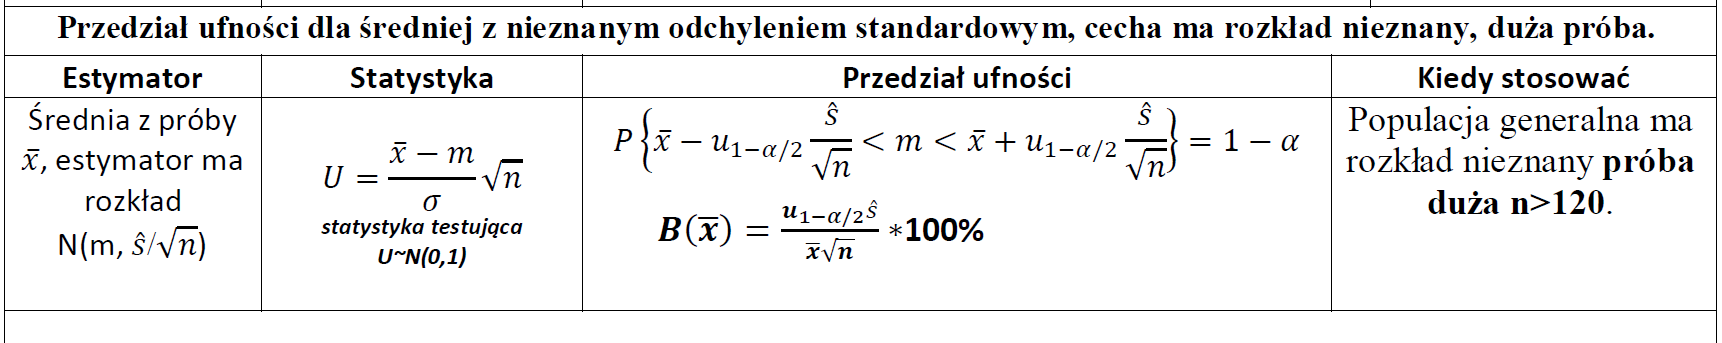

alfa=0.01;
n=length(rozegrane_gry)

n = 14042

srednia=mean(rozegrane_gry)

srednia = 0.4385

odchylenie_standardowe=std(rozegrane_gry)

odchylenie_standardowe = 0.0926

kwantyl=icdf('normal', (1-alfa/2), 0, 1)

kwantyl = 2.5758

przedzial_ufnosci=[srednia-kwantyl*odchylenie_standardowe/sqrt(n), srednia+kwantyl*(odchylenie_standardowe/sqrt(n))]

przedzial_ufnosci =     0.4365    0.4406


% precyzja szacowania
B=(kwantyl*odchylenie_standardowe)/(srednia*sqrt(n))*100

B = 0.4592

B<5% -> duża precyzja szacowania

# **Dla poziomu  ufności 1-alfa=0.99   przedział  ufności dla średniej "skuteczność graczy mvp w grach" wynosi  0.4365<srednia< 0.4406  Względna precyzja  0.4592 (duża precyzja)**

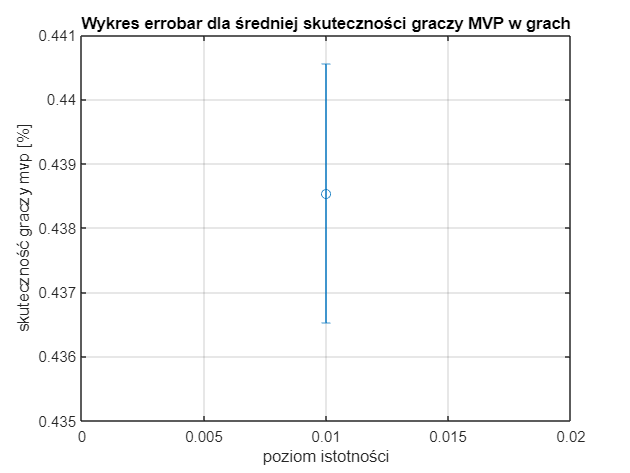

% errorbar dla sredniej
x=0.01;
y=srednia;
figure
% errorbar dla średniej i przedział ufności 1-alfa=0.95
errorbar(x,y,srednia-przedzial_ufnosci(1), przedzial_ufnosci(2)-srednia,'o')
grid on
ylim([0.435, 0.4410])
xlim([0 0.02])
title('Wykres errobar dla średniej skuteczności graczy MVP w grach')
xlabel('poziom istotności')
ylabel('skuteczność graczy mvp [%]')

% estymacja punktowa
% blad standardowy sredniej
D=odchylenie_standardowe/sqrt(n)

D = 7.8181e-04

% blad wzgledny
V=(D/srednia)*100

V = 0.1783

V<7.5% wysoce precyzyjna estymacja

# `Korelacja - zależność pozycji i skuteczności gracza`

`*skoro pozycja jest zmienną kategoryczną, to nie mówimy o korelacji, ale o zależności`

clearvars
% korelacja pozycja a skuteczność
dane=readtable('player_mvp_stats.csv');

dane=rmmissing(dane);
dane_pozycja=table2array(dane(:,2));
dane_skutecznosc=table2array(dane(:,10));
tabela=table(dane_pozycja, dane_skutecznosc)

tabela = 11817×2 table
    dane_pozycja    dane_skutecznosc
    ____________    ________________

       {'PF'}            0.476      
       {'SG'}            0.477      
       {'SF'}            0.492      
       {'PG'}            0.432      
       {'PG'}            0.477      
       {'C' }            0.496      
       {'PF'}            0.495      
       {'SG'}            0.443      
       {'SG'}            0.441      
       {'C' }            0.565      
       {'PF'}            0.476      
       {'SG'}            0.458      
       {'SF'}            0.469      
       {'PF'}            0.407      
       {'PG'}            0.222      
       {'C' }            0.448      


**H0: Cechy statystyczne są niezależne stochastycznie (nie ma zależności pomiędzy pozycją, a skutecznością gracza)**

**H1: Cechy statystyczne są zależne stochastycznie (występuje zależność między pozycją, a skutecznością gracza)**

[table, chi2, p]=crosstab(dane_pozycja, dane_skutecznosc)

table =      0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     2     1     0     0     0     1     1     0     0     0     0     7     0     0     1     0     1     0     0     0     0     0     0     0
     7     1     2     1     0     0     1     4     1     0     0     0     2     2     0     0     0     0     0     6     1     1     0     0     3     0     0     0     1     3     0     0     0     1     0     1     1    11     0     0     0     1     0     0     0     6     0     2     3     0
     3     0     1     0     0     1     0     3     0     0     0     0     0     1     0     0     0     0     0     3     0     0     0     0     2     0     2     0     0     1     0     2     1     1     2     0     0     8     1     1     0     0     0     0     0     0     2     0     1     1
     8     1     0     0     1     0     0     1     0     1     1     1     1     4     

chi2 = 8.4114e+03

p = 1.5974e-40

p-value<alfa, należy odrzucić H0. Istnieje zależność między pozycją, a  skutecznością gracza

unique_names=unique(dane_pozycja)

unique_names = 16×1 cell array
    {'C'    }
    {'C-PF' }
    {'PF'   }
    {'PF-C' }
    {'PF-SF'}
    {'PG'   }
    {'PG-SF'}
    {'PG-SG'}
    {'SF'   }
    {'SF-C' }
    {'SF-PF'}
    {'SF-SG'}
    {'SG'   }
    {'SG-PF'}
    {'SG-PG'}
    {'SG-SF'}


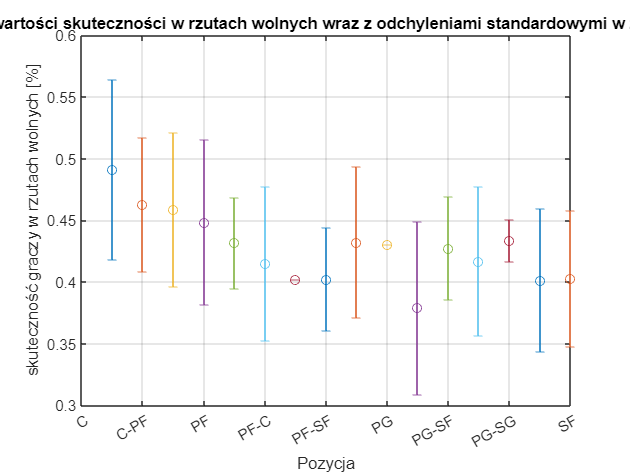

tabela=sortrows(tabela);

skutecznosc_C_tabela=tabela(1:1674,:);
srednia_C=mean(skutecznosc_C_tabela.("dane_skutecznosc"));
skutecznosc_CPF_tabela=tabela(1675:1693,:);
srednia_CPF=mean(skutecznosc_CPF_tabela.("dane_skutecznosc"));
skutecznosc_PF_tabela=tabela(1694:3988,:);
srednia_PF=mean(skutecznosc_PF_tabela.("dane_skutecznosc"));
skutecznosc_PFC_tabela=tabela(3989:4007,:);
srednia_PFC=mean(skutecznosc_PFC_tabela.("dane_skutecznosc"));
skutecznosc_PFSF_tabela=tabela(4008:4028,:);
srednia_PFSF=mean(skutecznosc_PFSF_tabela.("dane_skutecznosc"));
skutecznosc_PG_tabela=tabela(4029:6622,:);
srednia_PG=mean(skutecznosc_PG_tabela.("dane_skutecznosc"));
skutecznosc_PGSF_tabela=tabela(6623:6623,:);
srednia_PGSF=mean(skutecznosc_PGSF_tabela.("dane_skutecznosc"));
skutecznosc_PGSG_tabela=tabela(6624:6652,:);
srednia_PGSG=mean(skutecznosc_PGSG_tabela.("dane_skutecznosc"));
skutecznosc_SF_tabela=tabela(6653:9028,:);
srednia_SF=mean(skutecznosc_SF_tabela.("dane_skutecznosc"));
skutecznosc_SFC_tabela=tabela(9029:9029,:);
srednia_SFC=mean(skutecznosc_SFC_tabela.("dane_skutecznosc"));
skutecznosc_SFPF_tabela=tabela(9030:9051,:);
srednia_SFPF=mean(skutecznosc_SFPF_tabela.("dane_skutecznosc"));
skutecznosc_SFSG_tabela=tabela(9052:9082,:);
srednia_SFSG=mean(skutecznosc_SFSG_tabela.("dane_skutecznosc"));
skutecznosc_SG_tabela=tabela(9083:11762,:);
srednia_SG=mean(skutecznosc_SG_tabela.("dane_skutecznosc"));
skutecznosc_SGPF_tabela=tabela(11763:11766,:);
srednia_SGPF=mean(skutecznosc_SGPF_tabela.("dane_skutecznosc"));
skutecznosc_SGPG_tabela=tabela(11767:11791,:);
srednia_SGPG=mean(skutecznosc_SGPG_tabela.("dane_skutecznosc"));
skutecznosc_SGSF_tabela=tabela(11792:11817,:);
srednia_SGSF=mean(skutecznosc_SGSF_tabela.("dane_skutecznosc"));
nazwy=["C", "C-PF", "PF" ,"PF-C", "PF-SF", "PG", "PG-SF", "PG-SG", "SF", "SF-C", "SF-PF", "SF-SG", "SG", "SG-PF", "SG-PG", "SG-SF"];
srednie=[srednia_C, srednia_CPF, srednia_PF, srednia_PFC, srednia_PFSF, srednia_PG, srednia_PGSF, srednia_PGSG, srednia_SFPF, srednia_SF, srednia_SFC, srednia_SFSG, srednia_SG, srednia_SGPF, srednia_SGPG, srednia_SGSF];
odchylenia=[std(skutecznosc_C_tabela.("dane_skutecznosc")), std(skutecznosc_CPF_tabela.("dane_skutecznosc")), std(skutecznosc_PF_tabela.("dane_skutecznosc")), std(skutecznosc_PFC_tabela.("dane_skutecznosc")), std(skutecznosc_PFSF_tabela.("dane_skutecznosc")), std(skutecznosc_PG_tabela.("dane_skutecznosc")), std(skutecznosc_PGSF_tabela.("dane_skutecznosc")),  std(skutecznosc_PGSG_tabela.("dane_skutecznosc")), std(skutecznosc_SF_tabela.("dane_skutecznosc")), std(skutecznosc_SFC_tabela.("dane_skutecznosc")), std(skutecznosc_SFPF_tabela.("dane_skutecznosc")), std(skutecznosc_SFSG_tabela.("dane_skutecznosc")), std(skutecznosc_SG_tabela.("dane_skutecznosc")),  std(skutecznosc_SGPF_tabela.("dane_skutecznosc")),std(skutecznosc_SGPG_tabela.("dane_skutecznosc")) ,std(skutecznosc_SGSF_tabela.("dane_skutecznosc"))];
figure;
for i=1:16
    errorbar(i,srednie(i),odchylenia(i), odchylenia(i), 'o')
    hold on
end
xticklabels(nazwy)
grid on
title('Wykres średnich wartości skuteczności w rzutach wolnych wraz z odchyleniami standardowymi w zależności od pozycji')
xlabel('Pozycja')
ylabel('skuteczność graczy w rzutach wolnych [%]')

function H=chi2test(x, alpha)
%   CHI2TEST: Single sample Pearson Chi Square goodness-of-fit hypothesis test.
%   H=CHI2TEST(X,ALPHA) performs the particular case of Pearson Chi Square
%   test to determine whether the null hypothesis of composite normality PDF is 
%   a reasonable assumption regarding the population distribution of a random sample X
%   with the desired significance level ALPHA.
%
%   H indicates the result of the hypothesis test according to the MATLAB rules 
%   of conditional statements:
%   H=1 => Do not reject the null hypothesis at significance level ALPHA.
%   H=0 => Reject the null hypothesis at significance level ALPHA.
% 
%   The Chi Square hypotheses and test statistic in this particular case are:
% 
%   Null Hypothesis:        X is normal with unknown mean and variance.
%   Alternative Hypothesis: X is not normal.
%
%   The random sample X is shifted by its estimated mean and normalized by its
%   estimated standard deviation. The tested bins XP of the assumed normal distribution
%   are chosen [-inf, -1.6:0.4:1.6, inf] to avoid unsufficient statistics. 
%   
%   Let E(x) be the expected frequency X falls within XP according to the normal
%   distribution and O(x) be the observed frequency. The Pearson statistic, 
%   X2=SUM((E(x)-O(x))^2/E(x)) distributes Chi Square with length(XP)-3 degrees
%   of freedom. 
%
%   The decision to reject the null hypothesis is taken when the P value (probability that Chi2
%   random value with length(XP)-3 degrees of freedomd is greater than X2) is less than 
%   significance level ALPHA. 
%
%   X must be a row vector representing a random sample. ALPHA must be a scalar.
%   The function doesn't check the formats of X and ALPHA, as well as a number of the
%   input and output parameters.
%
%   The asymptotic limit of the Chi Square test presented is reached when LENGTH(X)>90.
%
% Acknowledge: Dr. S. Loyka
%
% Author: G. Levin, May, 2003.
%
% References:
%   W. T. Eadie, D. Drijard, F. E. James, M Roos and B. Sadoulet, "Statistical Methods
%   in Experimental Physics", North-Holland, Sec. Reprint, 1982.

%Normalize x
N=length(x);
x=(x-mean(x))/std(x); %standardization

xp=[-inf, -1.6:.4:1.6, inf]; %tested bins
E=0.5*N*diff(erfc(-xp/sqrt(2))); %expected frequency
S=histc(x, xp); 
O=S(1:end-1); %%observed frequency
%plot(xp(2:end),E,'k-',xp(2:end),O,'k.');
x2=sum((E-O).^2./E); %statistics

pval=1-gammainc(x2/2,(length(O)-3)/2); %p value

H=(pval>=alpha);
end